# ***Flow pack machine***

clc; clear; close all;
set(0, 'defaultAxesTickLabelInterpreter','latex'); 
set(0, 'defaultlegendInterpreter','latex')

#### Design specifications (reference conditions)

L= 0.066; %[m] product's length
P= 788; %productivity [pcs/min]
n= 3; % number of working heads
Rp= 0.045;%[m] radius of working heads
Jr= 11.5e-3;%[kg*m^2] moment of inertia of the drums, gears included, reflected to the trasmission's output
theta_zero= 30; %[°] working angle


#### Problem definition

v0= (P*L)/60; %line speed [m/s]
T= L/v0; %cycle time [s]
Lp= (2*pi*Rp)/n; %peripheral distance between adiacent working heads
disp(['line speed   v0= ', num2str(v0),' [m/s]'] )

line speed   v0= 0.8668 [m/s]


disp(['cycle time   T= ', num2str(T),' [s]'] );

cycle time   T= 0.076142 [s]


disp(['peripheral distance between heads   Lp= ', num2str(Lp),' [m]'] );

peripheral distance between heads   Lp= 0.094248 [m]


#### Motion law

ts= (theta_zero*(pi/180)*Rp)/v0; %tempo di lavoro
h= Lp-L; %alzata
ta= T-ts; % variable speed time

%legge ad accelerazione costante 1/3 1/3 1/3
Cv= 1.5;
Ca= 4.5;

vr_max= v0+Cv*(h/ta);
ar_max= Ca*(h/ta^2);
ar_rms=sqrt((2/3)*(ta/T))*ar_max;
disp(['velocità periferica massima = ', num2str(vr_max),' [m/s]'] )

velocità periferica massima = 1.7322 [m/s]


disp(['accelerazione massima = ', num2str(ar_max),' [m/s^2]'] );

accelerazione massima = 53.0303 [m/s^2]


disp(['accelerazione rms = ', num2str(ar_rms),' [m/s^2]'] );

accelerazione rms = 34.7203 [m/s^2]


**VELOCITA'**

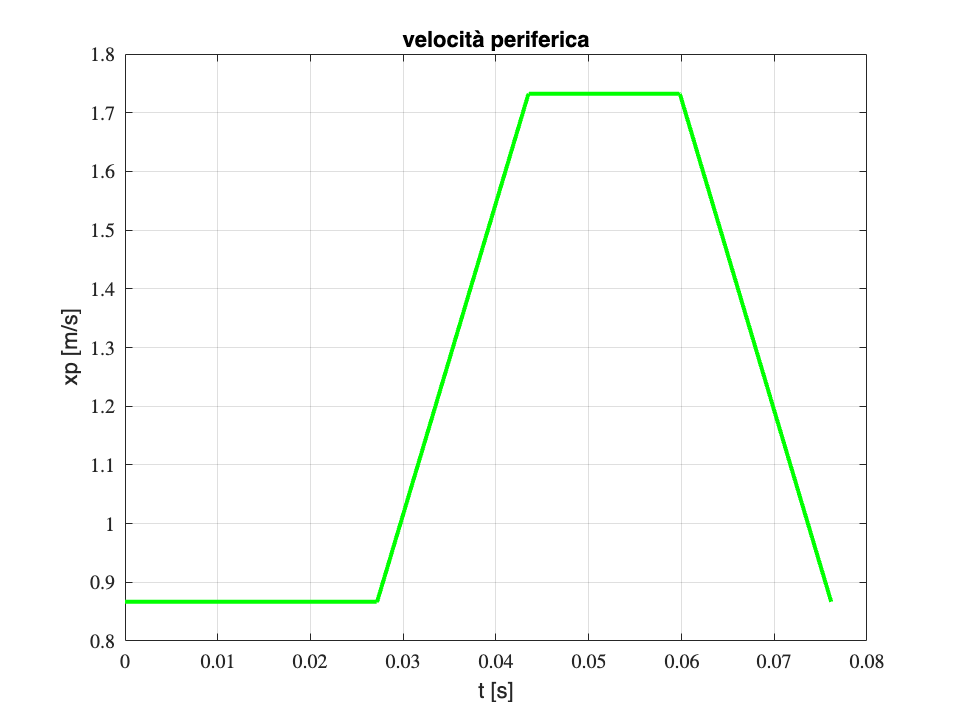

nxp = [v0    v0     vr_max      vr_max       v0    ]; % velocità per punti
nt  = [0      ts    ts+ta/3    ts+2*ta/3      ts+ta]; % vettore tempo

t=linspace(nt(1),nt(end),1000);
xp =interp1(nt,nxp, t);

w = xp./Rp; %velocità angolare

w_max=max(abs(w)); %rad/s
w_rms=rms(w);


figure
plot(t, xp,'g','linewidth',2)
grid on
title('velocità periferica')
 xlabel('t [s]');
 ylabel('xp [m/s]');

**ACCELERAZIONE**

 nxpp = [0       0      ar_max           ar_max       0                   0         -ar_max                -ar_max  ]; % accelerazione per punti
nt  =   [0      ts      ts+0.000001      ts+ta/3       ts+ta/3+0.000001   ts+2*ta/3    ts+2*ta/3+0.000001      ts+ta]; % vettore tempo

t=linspace(nt(1),nt(end),1000);
xpp =interp1(nt,nxpp, t);

wp= xpp./Rp;% accelerazione angolare
wp_max=max(abs(wp)) %rad/s^2

wp_max = 1.1785e+03

wp_rms=rms(wp) %rad/s^2

wp_rms = 771.8623

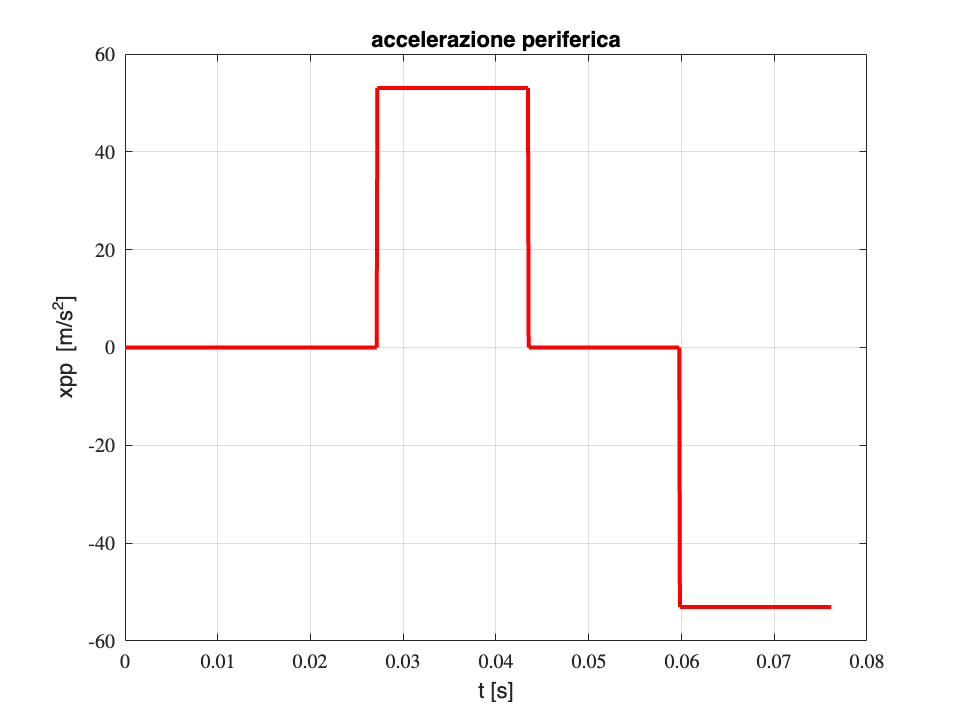



figure
plot(t, xpp,'r','linewidth',2)
grid on
title('accelerazione periferica')
 xlabel('t [s]');
 ylabel('xpp [m/s^2]');

**POSIZIONE**

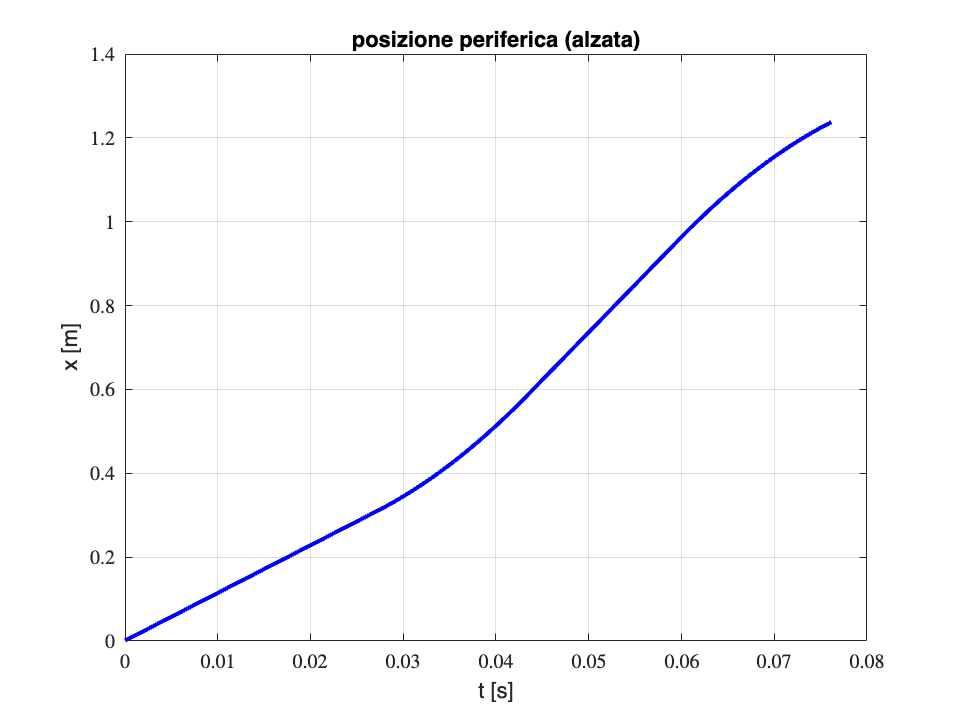

x = zeros(1,length(t));
 
for i=1:length(t)
    x(i) = sum(xp(1:i))/length(t);
end

figure
plot(t, x,'b','linewidth',2)
grid on
title('posizione periferica (alzata)')
 xlabel('t [s]');
 ylabel('x [m]');

### Calcolo coppia e potenza lato utilizzatore

%coppia
Cu=Jr.*wp; % coppia lato utilizzatore
Cu_rms=rms(Cu);
Cu_max=max(Cu)

Cu_max = 13.5522

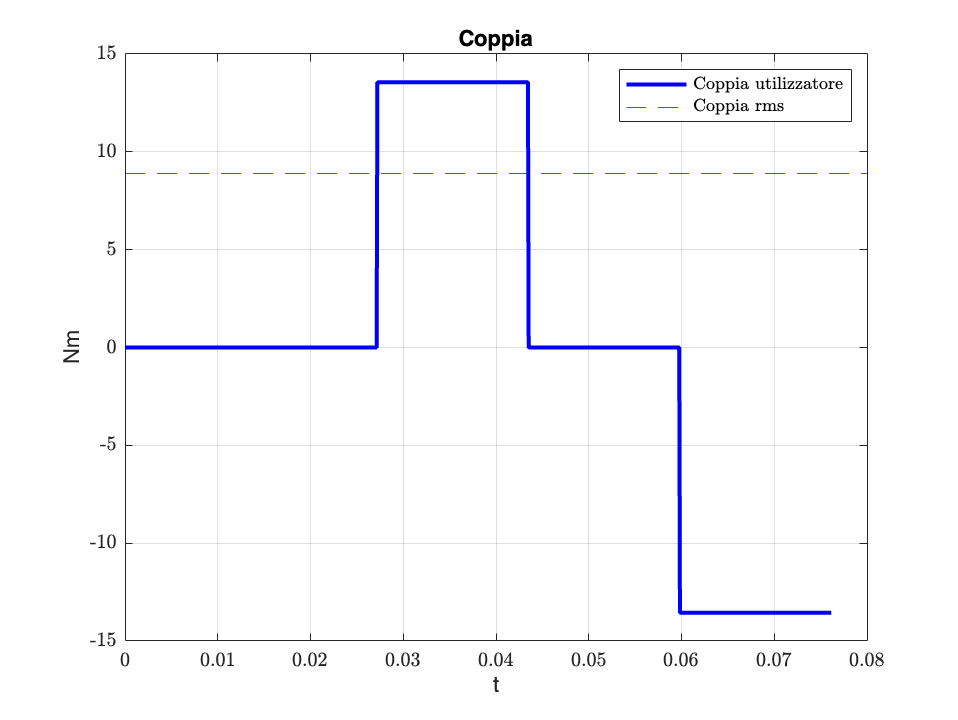


%potenza
Wu=Cu.*w;
Wu_rms=rms(Wu);

%rappresentazione

figure('color','white');
plot(t,Cu,'b','linewidth',2); 
hold on;grid on;
yline(Cu_rms,'b--')
xlabel('t');
ylabel('Nm')
legend('Coppia utilizzatore','Coppia rms')
title('Coppia');

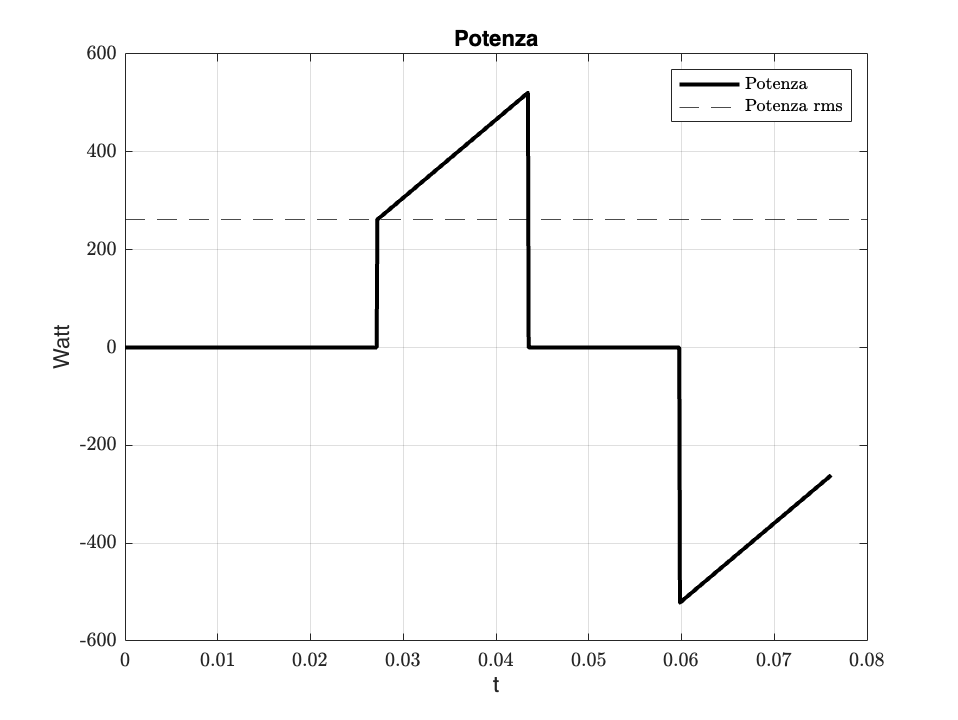


figure('color','white');
plot(t,Wu,'k','linewidth',2); 
hold on;grid on;
yline(Wu_rms,'k--')
xlabel('t');
ylabel('Watt')
legend('Potenza','Potenza rms')
title('Potenza');


Wu_max=max(abs(Wu))

Wu_max = 521.5365

Wu_rms=rms(Wu)

Wu_rms = 260.9439


Lc = mean(Cu.*wp)

Lc = 6.8514e+03

#### Dati per la scelta  inseriti nella  struttura Load

Load.Cu_rms= Cu_rms;    %coppia RMS  
Load.Lc = Lc;      %media del prodotto Cu*wc 
Load.wpc_rms= wp_rms;    %accelerazione RMS   
Load.wc_max= w_max;      %veloctà massima 
%%dati per nuova versione Adattamento_vers_1412
Load.Cu_max= Cu_max;    %coppia MAX  
Load.wpc_max= wp_max;    %accelerazione MAX  
Load.Jr = Jr;           %inerzia lato carico (trasmissioni incluse)


disp(Load);

     Cu_rms: 8.8764
         Lc: 6.8514e+03
    wpc_rms: 771.8623
     wc_max: 38.4943
     Cu_max: 13.5522
    wpc_max: 1.1785e+03
         Jr: 0.0115



### Scelta Motore 

Famiglia di trasmissioni scelta: ESP 60/1

% Velocità massima della trasmissione
nTMax=5000    

nTMax = 5000

Valore FcOTT = 165.546
Valore EcOTT = 4.1281
Tabella motori e rapporti di trasmissione
       Codice        CN        Jm       nMAX    Cm_max    nMAX1     Pm        Pm_max        Km        Fm      Fm_max      Em       IOTT      Imin      Imax 
    ____________    ____    ________    ____    ______    _____    _____    __________    ______    ______    ______    ______    ______    ______    ______

    {'b61.1.30'}     1.2       9e-05    3000      3.9     3000     16000      1.69e+05  

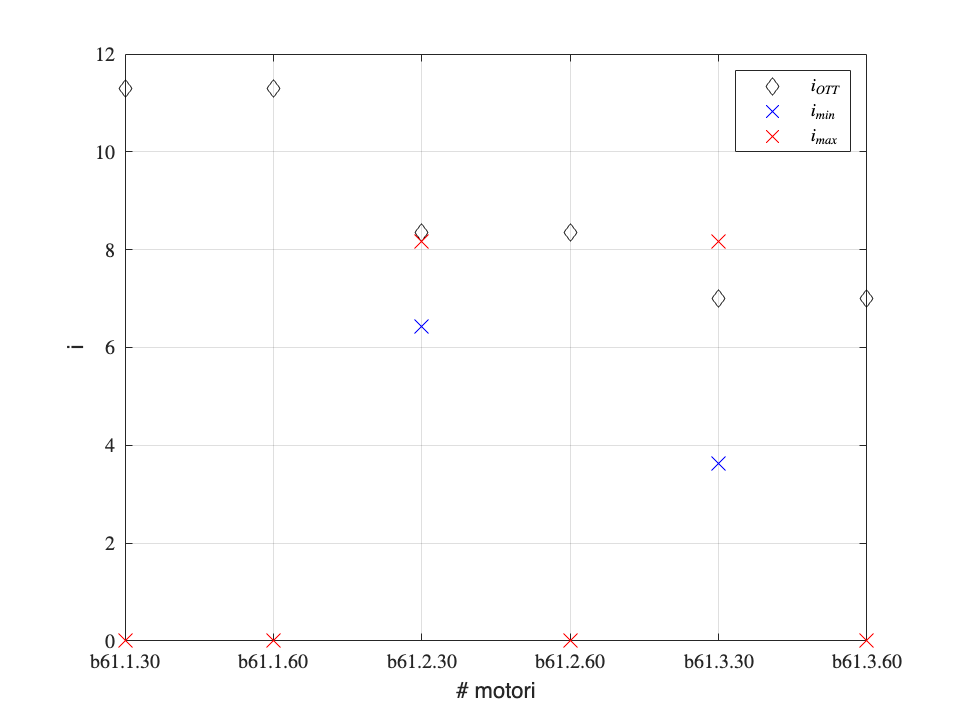

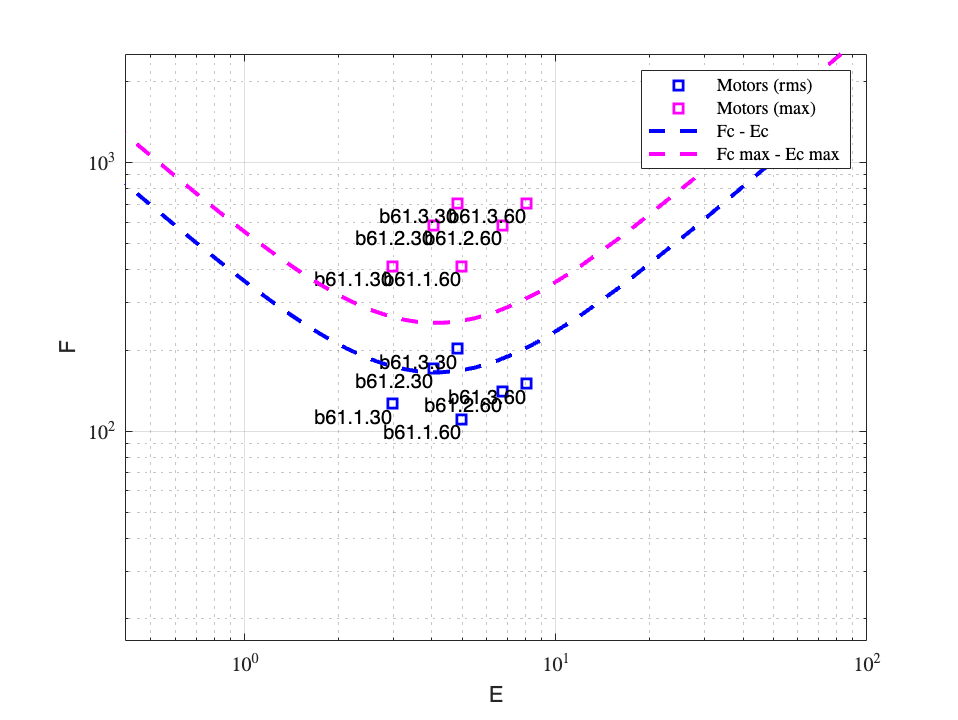


mot = AdattamentoDinamicoZAPPA(@DB_Mot1, Load, nTMax);

Dai dati si decide:

m=3; %motore scelto per la verifica

Cm_max=mot(m).Cm_max;
CN=mot(m).CN;
Jm=mot(m).Jm;
nMAX=min(nTMax,mot(m).nMAX);
wMAX=nMAX*2*pi/60;

disp('Tabella motore scelto');

Tabella motore scelto


Tablemot = struct2table(mot(m));  %solo per visualizzazione
disp(Tablemot);

     Codice     CN        Jm       nMAX    Cm_max    nMAX1     Pm        Pm_max        Km        Fm      Fm_max      Em       IOTT      Imin      Imax 
    ________    ___    ________    ____    ______    _____    _____    __________    ______    ______    ______    ______    ______    ______    ______

    b61.2.30    2.2    0.000165    3000     7.5      3000     29333    3.4091e+05    16.285    171.27    583.87    4.0354    8.3485    6.4229    8.1612



### Verifica

Con il  motore/riduttore scelto  si  calcola la coppia e la potenza erogata dal motore.    

Si  verifica che  $C_{rms}<C_N$ e si calcola il margine di coppia $M_C=\frac{C_N}{C_{rms}}$

Si rappresenta  il ciclo  di carico verificando che sia all'interno del campo intermittente  

**Verifica**

%rendimento,inerzia,rapporto T
G.Codice='ESP 60/1';
G.eta=0.95;
G.i=7.75;
G.JT=1.2e-6; % (valore j1 da tabella)
G.M2=40; %Nm coppia massima all'uscita

disp('Tabella riduttore scelto');

Tabella riduttore scelto


Tablemot = struct2table(G);  %solo per visualizzazione
disp(Tablemot);

     Codice     eta      i        JT       M2
    ________    ____    ____    _______    __

    ESP 60/1    0.95    7.75    1.2e-06    40




Cm_v=(Cu/(G.eta*G.i))+wp*G.i*(Jm+G.JT); %coppia motore di verifica
Cm_vrms=rms(Cm_v);
Wm_v=Cm_v.*w*G.i;
Cm_vmax=max(abs(Cm_v));
MC=CN/Cm_vrms; %determinare margine di coppia

nc=w*60/(2*pi);
n_mot=G.i*nc;

disp(['Valore di verifica RMS Cm_v = ', num2str(Cm_vrms)] );

Valore di verifica RMS Cm_v = 2.1998


disp(['Valore di verifica MAX Cm_v = ', num2str(Cm_vmax)] );

Valore di verifica MAX Cm_v = 3.3586


### **Ottimizzazione produttività**

OPTIMIZE FOR n° working heads = 1


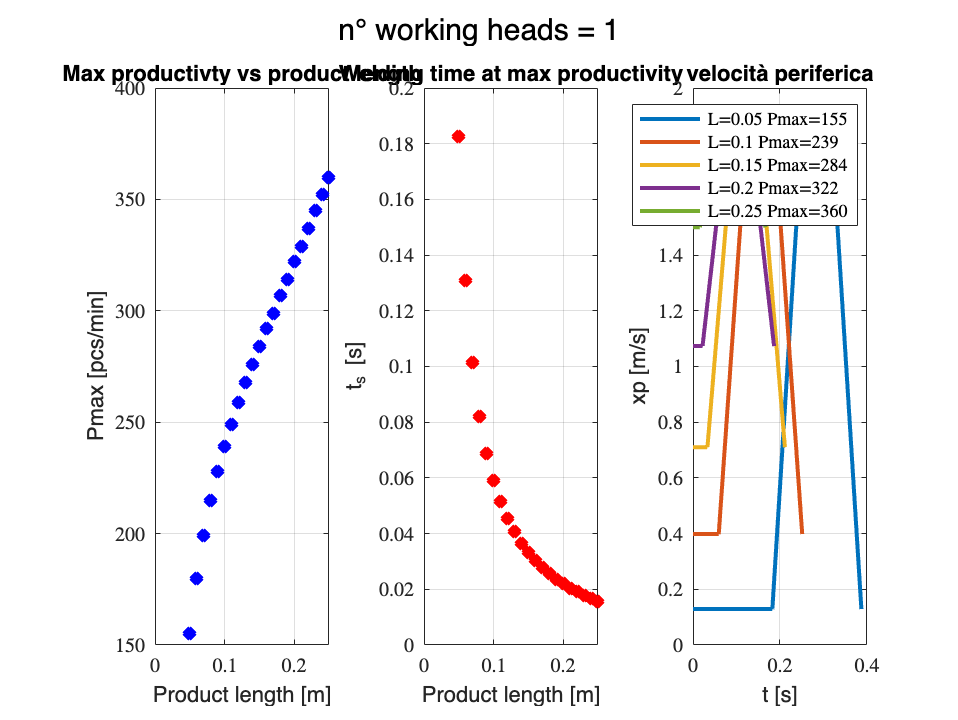

OPTIMIZE FOR n° working heads = 2


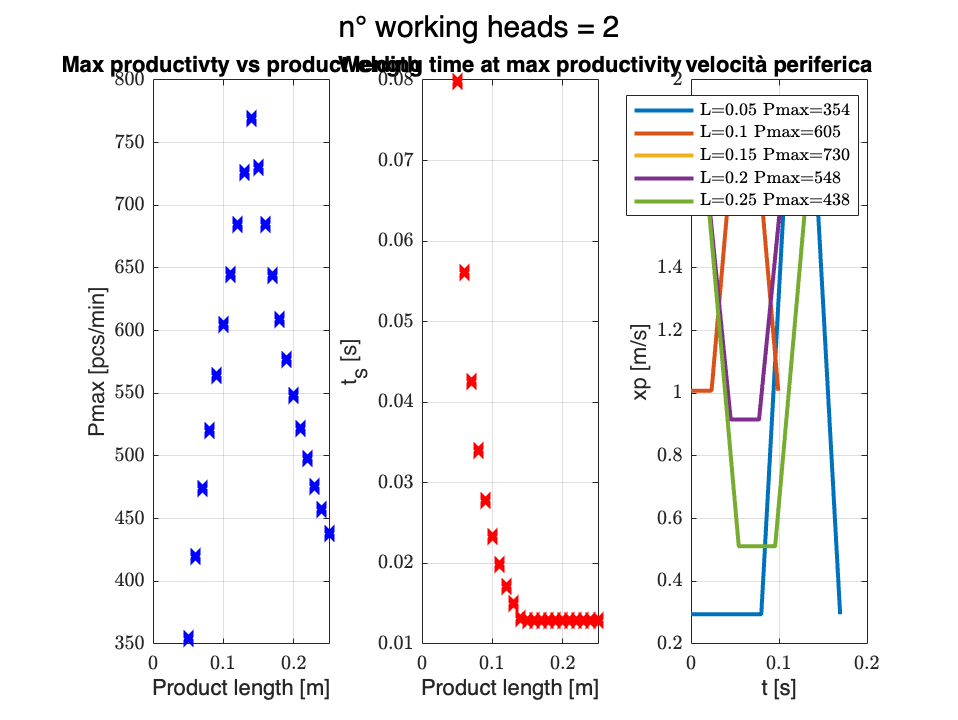

OPTIMIZE FOR n° working heads = 3


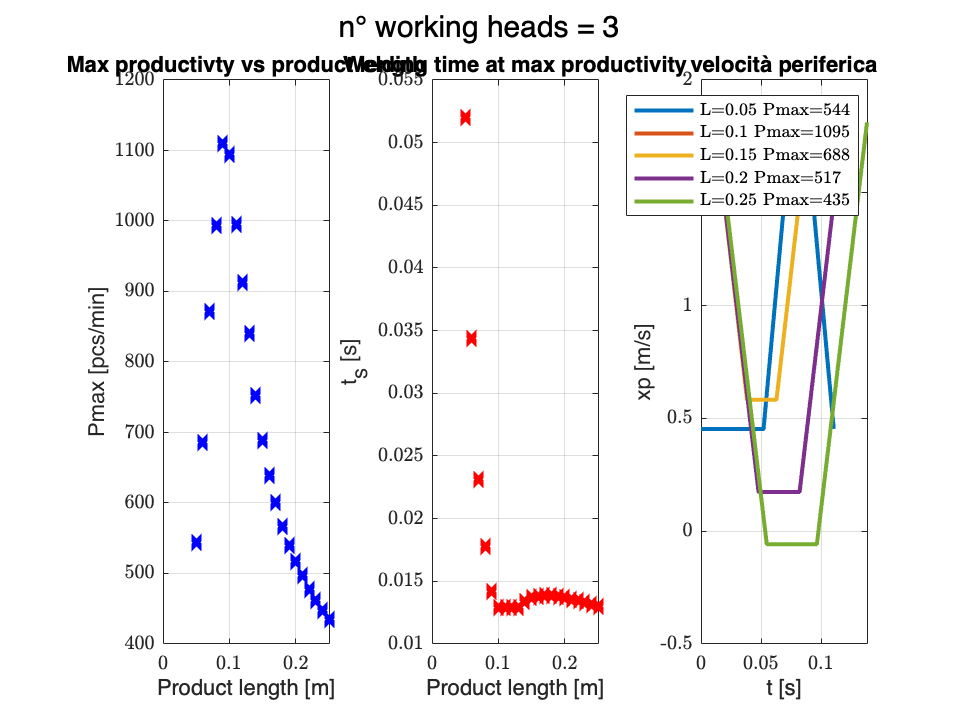

OPTIMIZE FOR n° working heads = 4


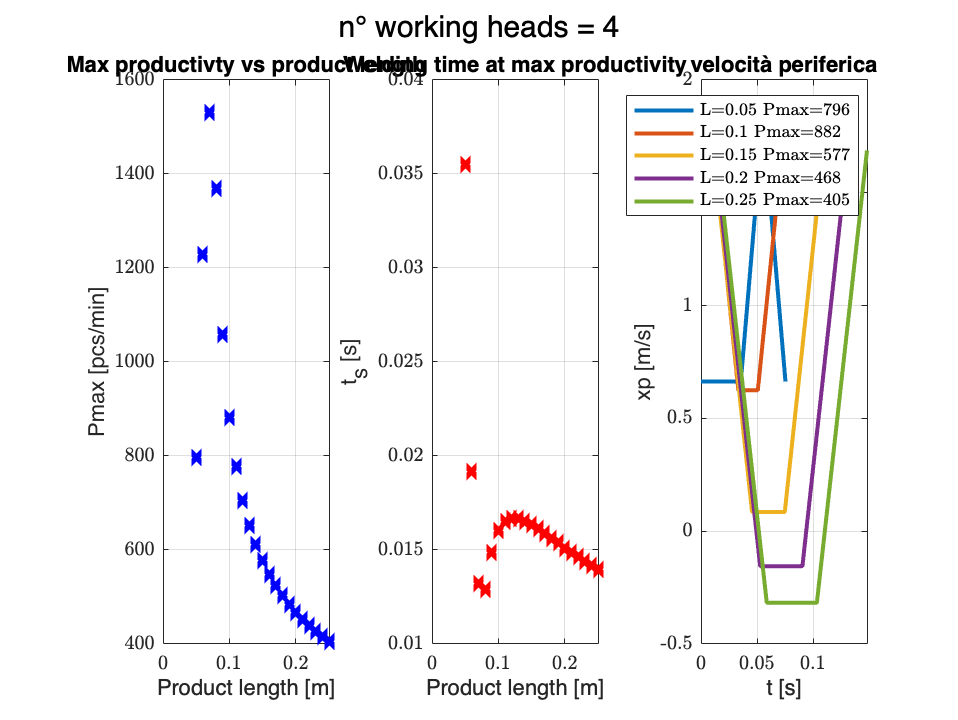

OttProduttivita(mot(m),G,nTMax)

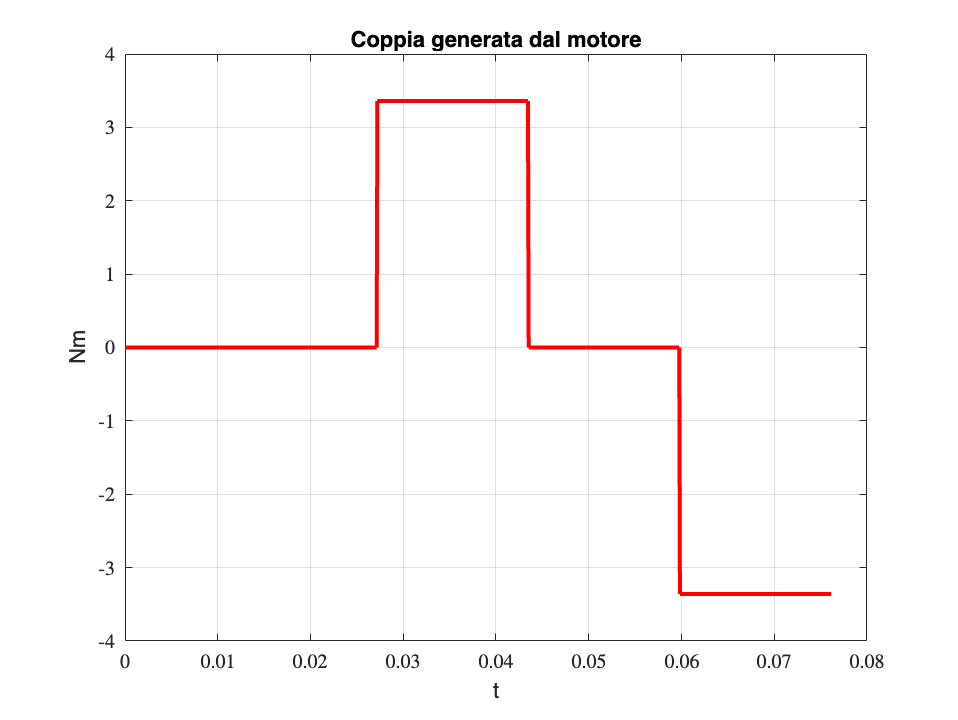

%andamento coppia e potenza
figure('color','white');
plot(t,Cm_v,'r','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Nm')
title('Coppia generata dal motore');

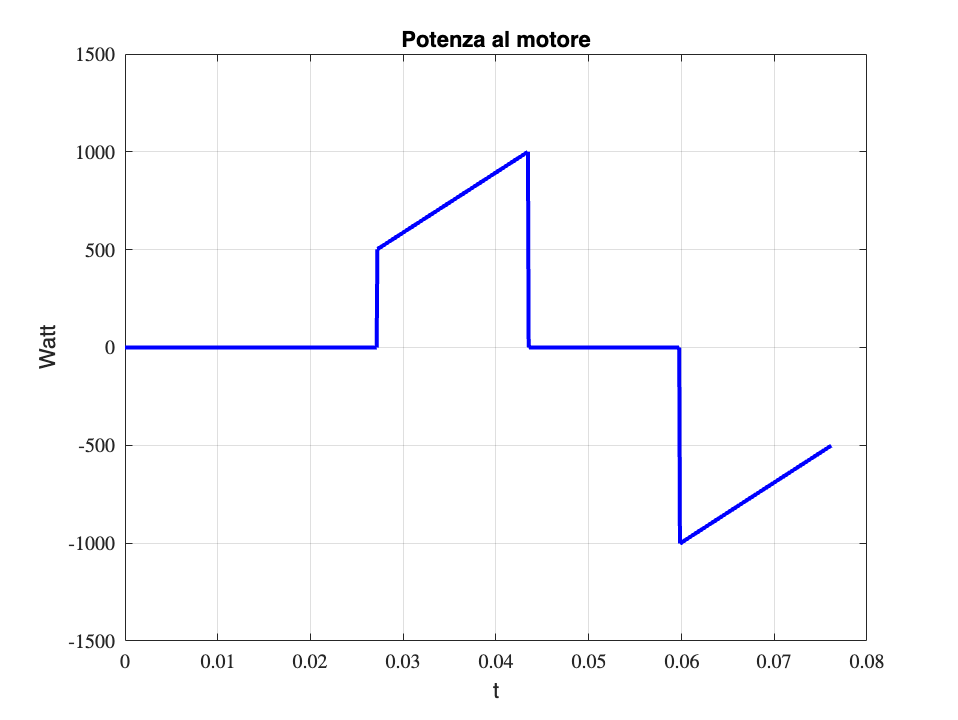


figure('color','white');
plot(t,Wm_v,'b','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Watt')
title('Potenza al motore');

**Verifica termica**

if(MC>1) disp(['Verifica termina soddisfatta, MC = ', num2str(MC), ' > 1'] );
    else disp(['Verifica termica non soddisfatta,  MC = ', num2str(MC), ' < 1'] );
end

Verifica termina soddisfatta, MC = 1.0001 > 1


**Verifica "picco di coppia" (ciclo di carico)**

Disegno le regioni S1 e Si (approssimazioni a rettangolo)

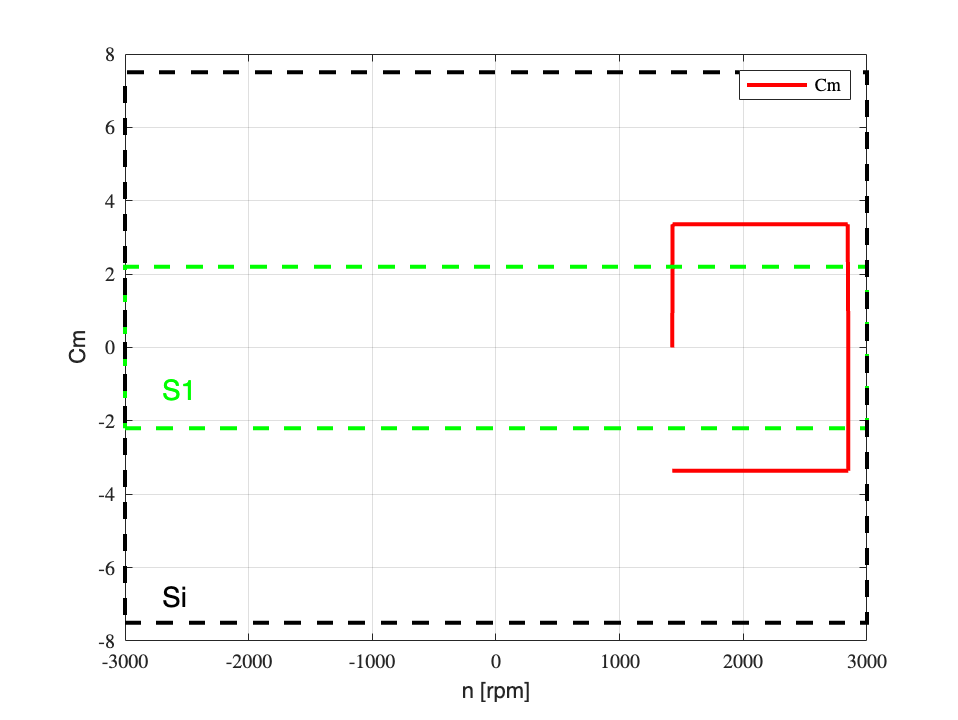

figure
plot(n_mot,Cm_v,'r','linewidth',2 )
rectangle('Position',[-nMAX -CN 2*nMAX 2*CN],'EdgeColor', 'g','LineStyle','--','linewidth',2) 
rectangle('Position',[-nMAX -Cm_max 2*nMAX 2*Cm_max],'EdgeColor','k','LineStyle','--','linewidth',2) 
grid on;
text(-nMAX+nMAX/10,-CN+CN/2,'S1','Color','g','FontSize',14)
text(-nMAX+nMAX/10,-Cm_max+Cm_max/10,'Si','Color','k','FontSize',14)

xlabel('n [rpm]')
ylabel('Cm')
legend('Cm')